# MAT 275 - Lab 5                                                   Bo-Chang, Lin

## The Mass-Spring System

### 
$$\begin{array}{l}
x\left(t\right)=\textrm{Acos}\left(\omega_0 t-\delta \right)\\
v\left(t\right)=\frac{\mathrm{d}}{\mathrm{d}t}x\left(t\right)=-A\omega_0 \sin \left(\omega_0 t-\delta \right)\\
A:\textrm{amplitude},\;\;T:\textrm{period},\;k:\textrm{spring}\;\textrm{constant},\;m:\textrm{mass}\\
\omega_0 =\frac{2\pi }{T}=\sqrt{\frac{k}{m}}:\textrm{angular}\;\textrm{frequency}\;\left(\frac{\textrm{rad}}{s}\right)\\
\delta :\textrm{phase}\;\textrm{angle}
\end{array}$$


# Exercise 1

**Givens:**

#### 
$$\begin{array}{l}
m=1\left(\textrm{kg}\right),\;k=4\left(N/m\right)\\
y\left(0\right)=y\prime \left(0\right)=-0\ldotp 6
\end{array}$$


(i.e. the mass is initially compressed upward 0.6 meters and released with an initial upward velocity of 0.6 m/s)

Notes: set downward direction positive.

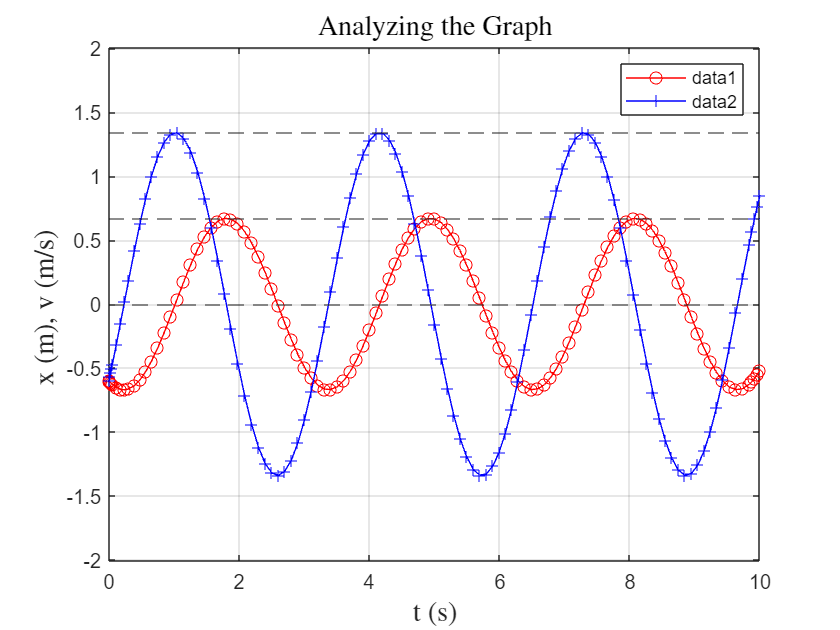

LAB05ex1a
legend("AutoUpdate","off")
yline([-2.01 2.01])
yline(0,"--")
[Ay, ~]=findpeaks(y);
yline(mean(Ay),"--")
[Av, ~]=findpeaks(v);
yline(mean(Av),"--")

### Part (a)

**Which curve represents y = y(t)? How do you know?**

One of the major differences between the two curves is amplitude. Looks like the blue one doubles red one. Given that $\omega_0$ = 2, which suggests that the red curve has to be y(t) because in a harmonic motion, the ratio of v(t) and y(t) in amplitude is the angular frequency ($\omega_0$)

#### 
$$y\left(t\right)=\textrm{Acos}\left(\omega_0 t-\delta \right);\;\;\;\;\;\;\;\;\;\;\;v\left(t\right)=\frac{\mathrm{d}}{\mathrm{d}t}y\left(t\right)=-A\omega_0 \sin \left(\omega_0 t-\delta \right)\;\;\;\;\;\;\;\;\;\;\;\;\;\Rightarrow \;\;\;\;\;\;\;\;\;\frac{|-A\omega_0 |}{A}=\omega_0$$


### Part (b)

**Find the period of the motion; first graphically (by reading the period from the graph) and then analytically (by finding the period using **$\omega_0$**).**

Graphically: since the x-axis is the timeline, the period is just the time interval between two peaks, the preiod of the motion looks like slightly above 3 seconds.

[~, i]=findpeaks(y);
Ty = (t(i(3)) - t(i(1)))/2; % more acurate to find the average between three peaks
disp(['The period of this motion is approximately ',num2str(Ty),' seconds.'])

The period of this motion is approximately 3.1423 seconds.


Analytically: given that the mass **m** = 1 (kg) and the spring constant **k** = 4 (N/m)


$${\textrm{Angular}\;\textrm{frequency}:\;\omega }_0 \;\left(\frac{\textrm{rad}}{s}\right)=\frac{2\pi }{T}=\sqrt{\frac{k}{m}}$$


We could get the period T = $\pi$

### Part (c)

**Will the mass ever come to rest? Why?**

Technically, yes. At the instant whem the mass reach either the top or the bottom, 

its instantaneous speed will be zero.

### Part (d)

**What is the amplitude of the oscillations for y?**

[Ay, ~]=findpeaks(y);
disp(['The the amplitude of the oscillations for y(t) is approximately ',num2str(mean(Ay)),' meters.'])

The the amplitude of the oscillations for y(t) is approximately 0.66925 meters.


### Part (e)

What is the maximum velocity (in magnitude) attained by the mass, and when is it attained?

format short
[MAXv, i]=findpeaks(abs(v));
T1 = array2table([MAXv, t(i), y(i)]);
T1.Properties.VariableNames(1:3) = {'v (m/s)','t (s)','y (m)'}

T1 = 6×3 table
    v (m/s)    t (s)       y (m)  
    _______    ______    _________
    1.3395     1.0451     0.037426
    1.3413     2.5985    -0.014386
    1.3347     4.2087     0.067423
    1.3381     5.6935     0.047603
    1.3391     7.2705    -0.039119
    1.3394     8.8438     0.035566

The mass reach maximum speed at equilibrium points every half period.

### Part (f)

**How does the size of the mass m and the stiffness k of the spring affect the motion?**

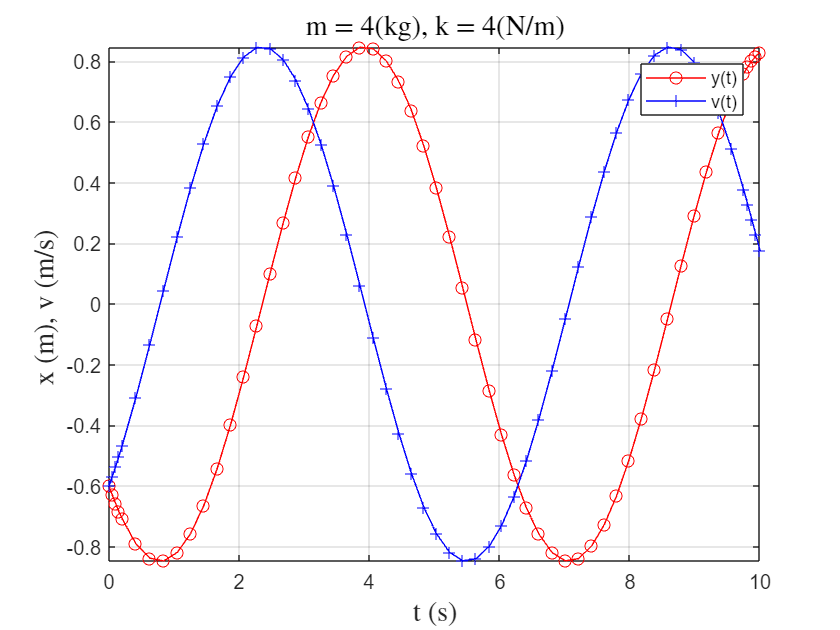

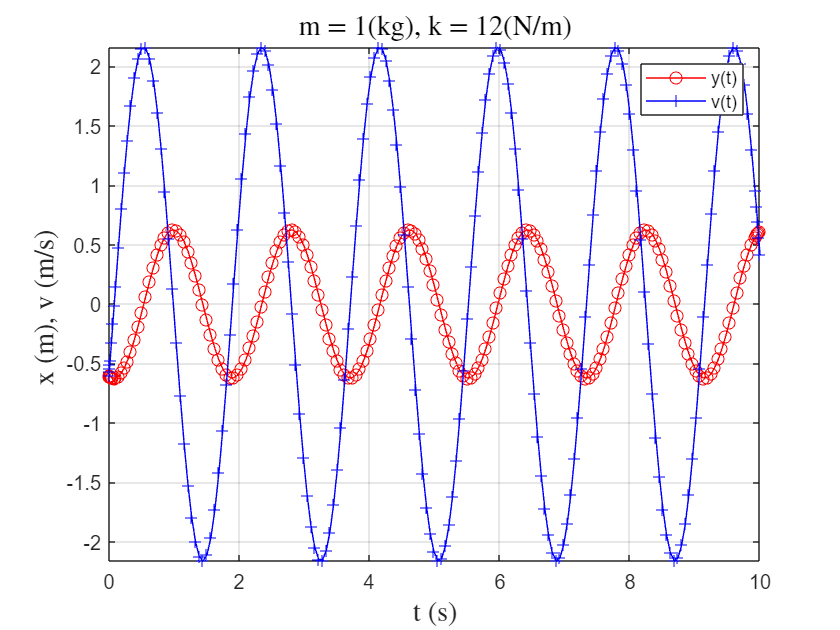

LAB05ex1f

Same spring with same k, the period become longer, moving slower, larger amplitude when mass increase. While, same mass but different spring, the period become shorter, moving faster, but amplitude remain the same when k increase.

# Exercise 2

type LAB05ex2

clear all;     % clear all variables 

m = 1;    % mass [kg]
k = 4;    % spring constant [N/m]
omega0 = sqrt(k/m); 
% initial conditions
y0 = -0.6;  
v0 = -0.6; 

[t,Y] = ode45(@f,[0,10],[y0,v0],[],omega0);   % solve for 0<t<10
y = Y(:,1); v = Y(:,2);                       % retrieve y, v from Y 
E = 0.5*m*v.^2 + 0.5*k*y.^2;

figure
plot(t,y,'ro-',t,v,'b+-')                     % time series for y, v, & E 
hold on
plot(t,E,LineWidth=2)
title("Analyzing the Graph","Interpreter","latex","FontSize",14)
legend("y(t)", "v(t)","Energy")
xlabel("t (s)","Interpreter","latex","FontSize",14)
ylabel("x (m), v (m/s) ","Interpreter","latex","FontSize",14)
axis tight
grid on


%---------------------------------------------------
function dYdt = f(t,Y,omega0); % function defining the DE 
y = Y(1); v = Y(2); 
dYdt=[ v ; - omega0^2*y ];
end


### Part (a)

**Is the energy conserved in this case?**

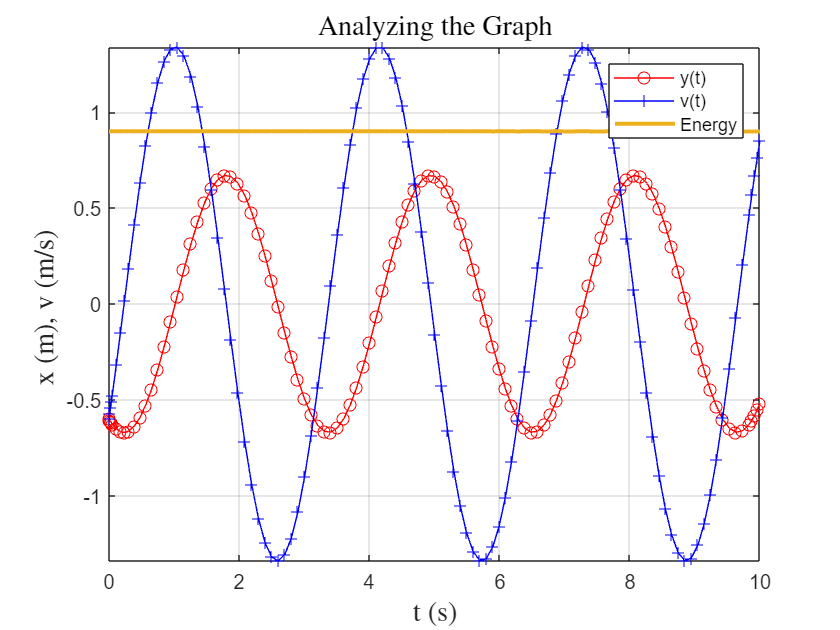

LAB05ex2

The graph confirms the fact that the energy is conserved. The total energy remain constant regardless of the movement of the mass.

### Part (b)

**Show analytically that:**$\frac{\textrm{dE}}{\textrm{dt}}=0$

- first differentiate $E\left(t\right)$ with respect to $t$ using the chain rule. 

- then make substitutions using the expression for $\omega_0$ and using the differential equation

#### 
$$\begin{array}{l}
\frac{d}{\textrm{dt}}\left(0\ldotp 5{m\cdot v\left(t\right)}^2 +0\ldotp 5{k\cdot y\left(t\right)}^2 \right)\\
=0\ldotp 5m\frac{d}{\textrm{dt}}{\left(-A\omega_0 \sin \left(\omega_0 t+\delta \right)\right)}^2 +0\ldotp 5k\frac{d}{\textrm{dt}}{\left(\textrm{Acos}\left(\omega_0 t+\delta \right)\right)}^2 \\
={\textrm{mA}}^2 \omega_0^3 \sin \left(\omega_0 t+\delta \right)\cos \left(\omega_0 t+\delta \right)-{\textrm{kA}}^2 \omega_0 \cos \left(\omega_0 t+\delta \right)\sin \left(\omega_0 t+\delta \right)\\
k=\omega_0^2 m\\
={\textrm{mA}}^2 \omega_0^3 \sin \left(\omega_0 t+\delta \right)\cos \left(\omega_0 t+\delta \right)-{\textrm{mA}}^2 \omega_0^3 \cos \left(\omega_0 t+\delta \right)\sin \left(\omega_0 t+\delta \right)=0
\end{array}$$


% for reference
syms t w b m k a
yt = a*cos(w*t+b);
vt = diff(yt,t);
dKEdt = diff(0.5*m*vt^2,t)

$$dKEdt = a^{2}\,m\,w^{3}\,\cos\left(b+t\,w\right)\,\sin\left(b+t\,w\right)$$

dUdt = diff(0.5*k*yt^2,t)

$$dUdt = -a^{2}\,k\,w\,\cos\left(b+t\,w\right)\,\sin\left(b+t\,w\right)$$

dEdt = dKEdt + subs(dUdt,k,w^2*m)

$$dEdt = 0$$

### Part (c)

**Plot v(t) vs y(t) (phase plot)**

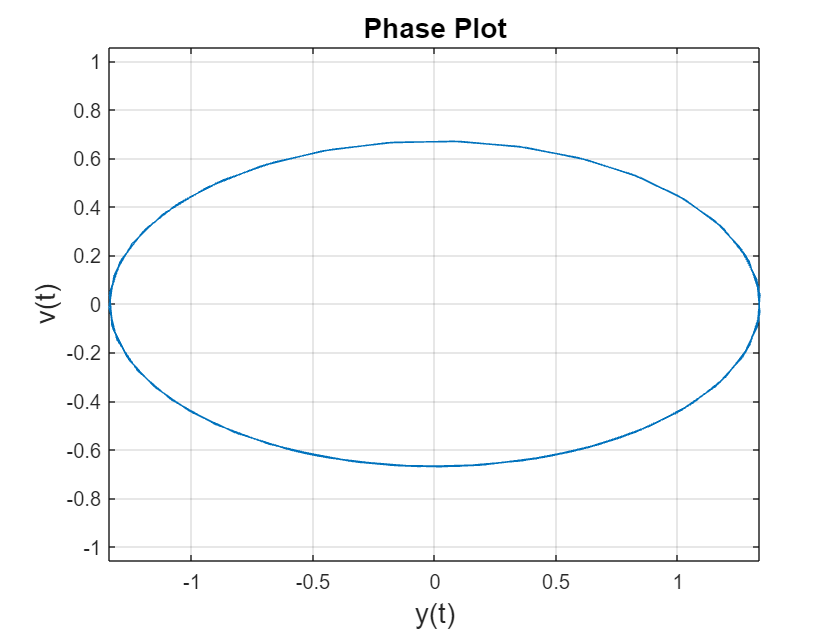

LAB05ex2; close % restore variables

figure; plot(v,y)
title("Phase Plot","FontSize",14)
xlabel("y(t)","FontSize",14)
ylabel("v(t)","FontSize",14)
axis equal; grid on

Since the energy is conservd and no dissipate force in this system, the mass will oscillating forever.

As a result, the graph would never get close to the origin.

# Exercise 3

## 
$$\begin{array}{l}
m\cdot {y^{\prime } }^{\prime } +c\cdot y^{\prime } +k\cdot y=0\\
y=x\left(t\right)=A_0 e^{-\textrm{pt}} \cos \left(\omega_0 t+\delta \right),\;\;\;p=\frac{c}{2m}
\end{array}$$


type LAB05ex3

clear all;     % clear all variables 

m = 1;  % mass [kg]
k = 4;  % spring constant [N/m]
c = 1;  % friction coefficient [Ns/m]
omega0 = sqrt(k/m); p = c/(2*m); 
% initial conditions
y0 =-0.6;  
v0 = -0.6; 

[t,Y] = ode45(@f,[0,10],[y0,v0],[],omega0, p);  % solve for 0<t<10
y = Y(:,1); v = Y(:,2);                         % retrieve y, v from Y 

figure
plot(t,y,'ro-',t,v,'b+-');                      % time series for y and v 
title("Damped Harmonic Motion","Interpreter","latex","FontSize",14)
legend("y(t)","v(t)=y'(t)","Interpreter","latex")
xlabel("t (s)","Interpreter","latex","FontSize",14)
ylabel("x (m), v (m/s) ","Interpreter","latex","FontSize",14)
grid on; axis tight; 


%---------------------------------------------------
function dYdt = f(t,Y,omega0,p);  % function defining the DE 
y = Y(1); v = Y(2); 
dYdt=[ v ; -omega0^2*y-2*p*v ];   % fill-in dv/dt
end


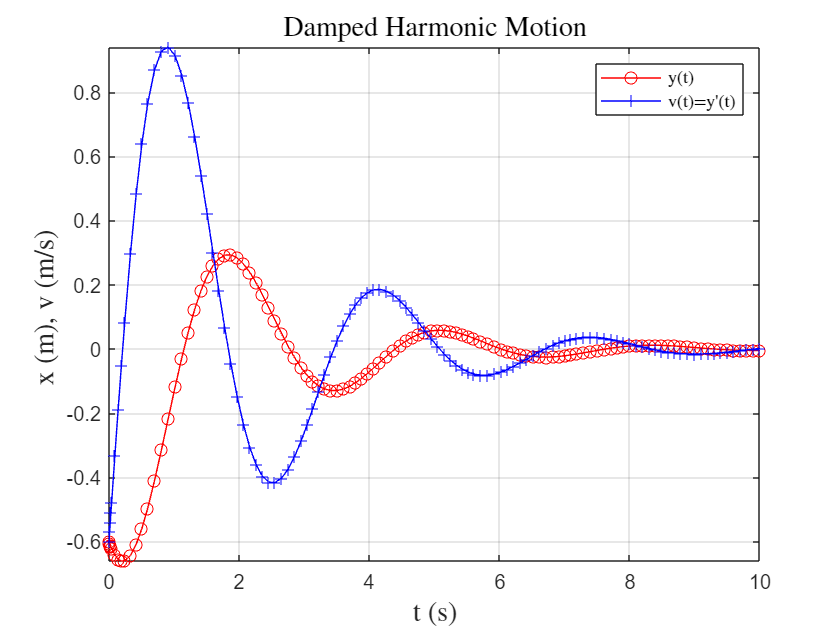

LAB05ex3

### Part (a)

**For what minimal time t1 will the mass-spring system satisfy |**`y(t)`**| < 0.05 for all t > t1?**

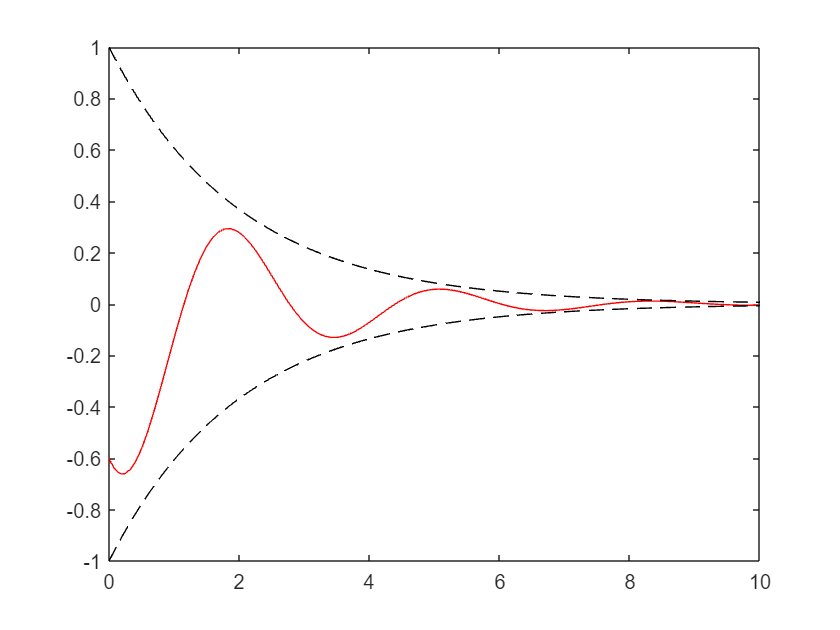

% for reference
figure
plot(t,y,'r',t,c*exp(-p*t),"k--",t,-c*exp(-p*t),"k--")

syms T
double(solve(c*exp(-p*T)==0.05,T)) % not the answer, for reference

ans = 5.9915

for i=1: length (y)
M(i)= max(abs(y(i:end )));
end
i = find (M <0.05); i = i(1);
disp ([ '|y| < 0.05 for t > t1 with ' num2str(t(i-1)) ' < t1 < ' num2str(t(i))])

|y| < 0.05 for t > t1 with 5.3398 < t1 < 5.4288


### Part (b)

**What is the largest (in magnitude) velocity attained by the mass, and when is it attained?**

format short
[MAXv, i]=findpeaks(abs(v));
T1 = array2table([MAXv, t(i), y(i)]);
T1.Properties.VariableNames(1:3) = {'v (m/s)','t (s)','y (m)'}

T1 = 6×3 table
    v (m/s)      t (s)       y (m)   
    ________    _______    __________
     0.94069    0.91124      -0.21581
     0.41703     2.5494      0.089291
     0.18545     4.1625      -0.04136
    0.082139     5.7118      0.024398
    0.036606     7.4012    -0.0083793
    0.016267     8.9884     0.0042941

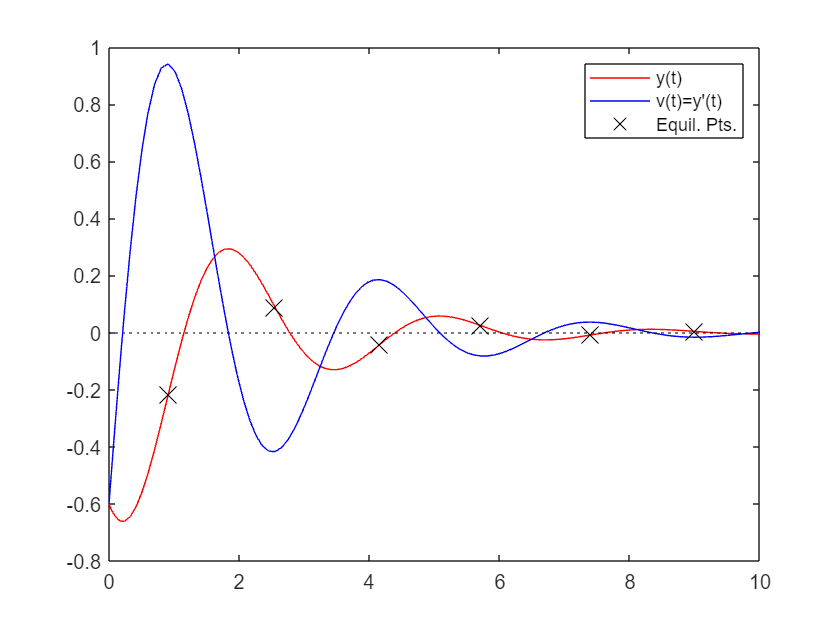

% for reference
figure
plot(t,y,"r",t,v,"b",t(i), y(i),"kx",MarkerSize=12)
legend("y(t)","v(t)=y'(t)","Equil. Pts.")
legend("AutoUpdate","off")
yline(0,"k:")

The largest speed of the mass is 0.94 (m/s) in this case, and it happens when the mass pass through the first equilibrium point at -0.216 (m).

### Part (c)

**How does the size of c affect the motion?**

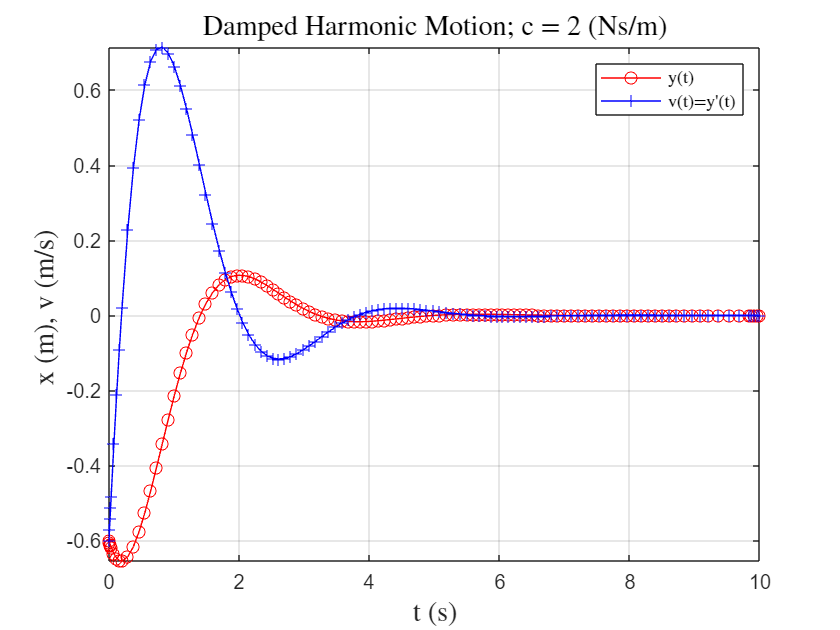

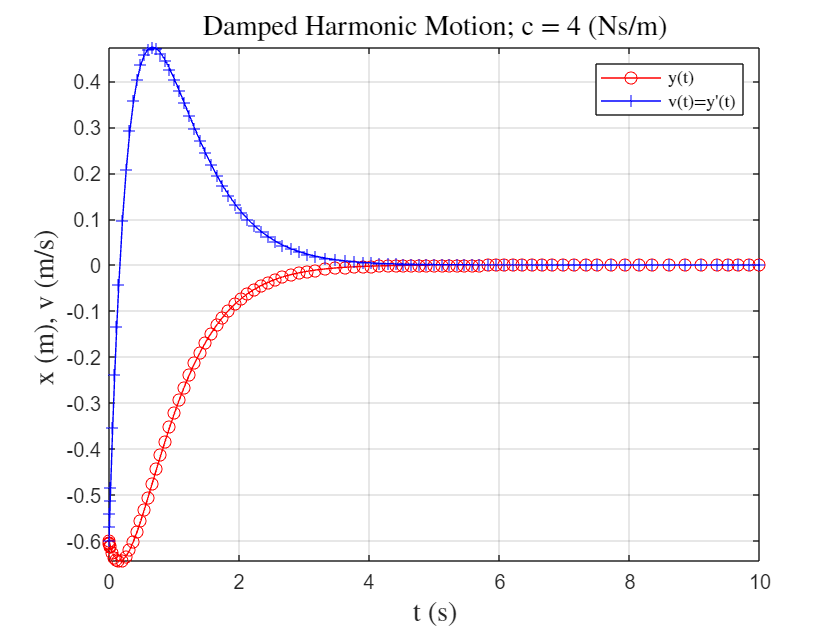

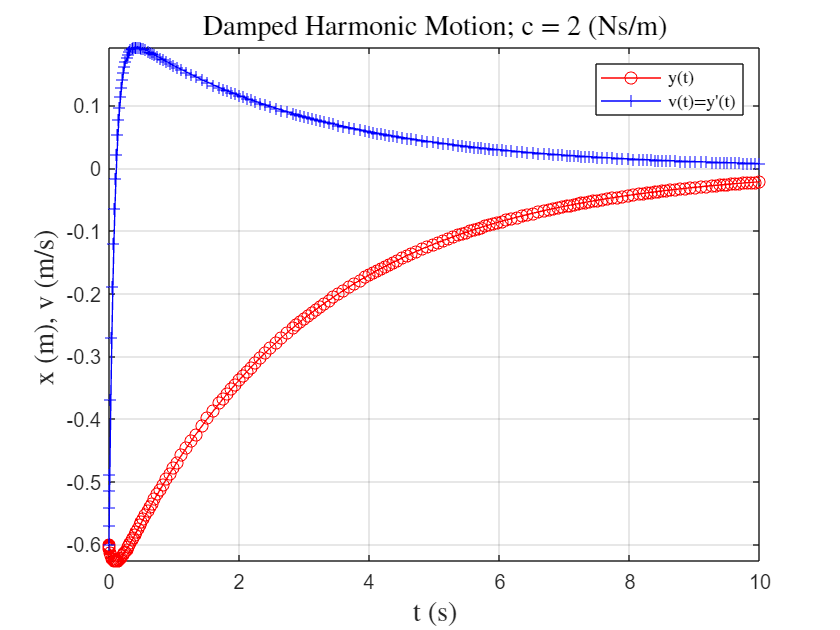

LAB05ex3c

### Part (d)

**What needs to happen (in terms of the characteristic equation) in order for there to be no oscillations? Impose a condition on the characteristic equation to find the critical c value. Write out main steps**

#### 
$$\begin{array}{l}
{m\cdot r}^2 +c\cdot r+k=0\\
r=\frac{-c\pm \sqrt{c^2 -4\textrm{mk}}}{2m}\\
D=0\\
c^2 -4\textrm{mk}=0\\
c_{\textrm{criticial}} =\sqrt{4\textrm{mk}}=\sqrt{4\cdot 1\cdot 4}=4\;\left(\frac{\textrm{Ns}}{m}\right)
\end{array}$$


# Exercise 4

type LAB05ex4 

clear all;     % clear all variables 

m = 1;  % mass [kg]
k = 4;  % spring constant [N/m]
c = 1;  % friction coefficient [Ns/m]
omega0 = sqrt(k/m); p = c/(2*m); 
% initial conditions
y0 =-0.6;  
v0 = -0.6; 

[t,Y] = ode45(@f,[0,10],[y0,v0],[],omega0, p);  % solve for 0<t<10
y = Y(:,1); v = Y(:,2);                         % retrieve y, v from Y 
E = 0.5*m*v.^2 + 0.5*k*y.^2;

figure
plot(t,y,'ro-',t,v,'b+-');                      % time series for y, v, & E 
hold on
plot(t,E,LineWidth=2)
title("Damped Harmonic Motion","Interpreter","latex","FontSize",14)
legend("y(t)","v(t)=y'(t)","Energy","Interpreter","latex")
xlabel("t (s)","Interpreter","latex","FontSize",14)
ylabel("x (m), v (m/s) ","Interpreter","latex","FontSize",14)
grid on; axis tight; 


%---------------------------------------------------
function dYdt = f(t,Y,omega0,p);  % function defining the DE 
y = Y(1); v = Y(2); 
dYdt=[ v ; -omega0^2*y-2*p*v ];   % fill-in dv/dt
end


### Part (a)

**Is the energy conserved in this case?**

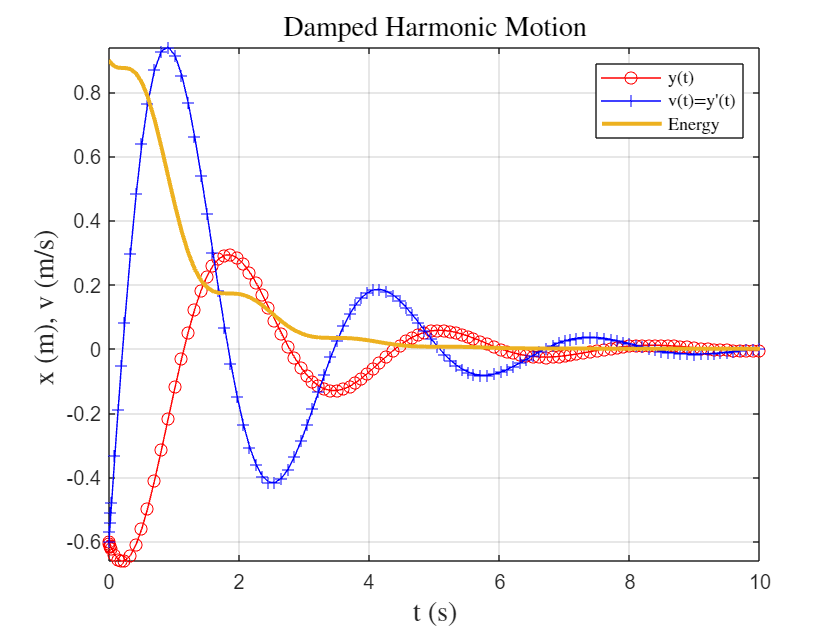

LAB05ex4

The graph shows the fact that the **mechanical energy** is not conserved in this case. The total energy mechanical energy diminish but transform into heat probably.

### Part (b)

**Find **$\displaystyle \frac{dE}{dt}$** using the chain rule and make substitutions based on the differential equation. You should reach an expression for **$\displaystyle \frac{dE}{dt}$** which is in terms of **$y^{\prime}$

#### 
$$\begin{array}{l}
m\cdot {y^{\prime } }^{\prime } +c\cdot y^{\prime } +k\cdot y=0\\
{y^{\prime } }^{\prime } =\frac{-\left(c\cdot y^{\prime } +k\cdot y\right)}{m}\\
\\
\frac{\textrm{dE}}{\textrm{dt}}=m\cdot v^{\prime } \cdot {v^{\prime } }^{\prime } +k\cdot y\cdot y^{\prime } \\
=m\cdot y^{\prime } \cdot {y^{\prime } }^{\prime } +k\cdot y\cdot y^{\prime } \\
=-\;c\cdot {\left(y^{\prime } \right)}^2 \\
\frac{\textrm{dE}}{\textrm{dt}}>0\;\;\;\textrm{when}\;\;\;c<0;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\frac{\textrm{dE}}{\textrm{dt}}<0\;\;\;\textrm{when}\;\;\;c>0
\end{array}$$


% for reference
syms y(t) v(t) m c k
v = diff(y,t);
d2y = -(c*diff(y,t)+k*y)/m;
dEdt = diff(0.5*m*v^2+0.5*k*y^2,t);
dEdt = subs(dEdt,diff(y,t,2),d2y)

$$dEdt(t) = k\,y\left(t\right)\,\frac{\partial }{\partial t}y\left(t\right)-\left(c\,\frac{\partial }{\partial t}y\left(t\right)+k\,y\left(t\right)\right)\,\frac{\partial }{\partial t}y\left(t\right)$$

disp(expand(dEdt))

$$-c\,{\left(\frac{\partial }{\partial t}y\left(t\right)\right)}^{2}$$

### Part (c)

**Plot v(t) vs y(t) (phase plot)**

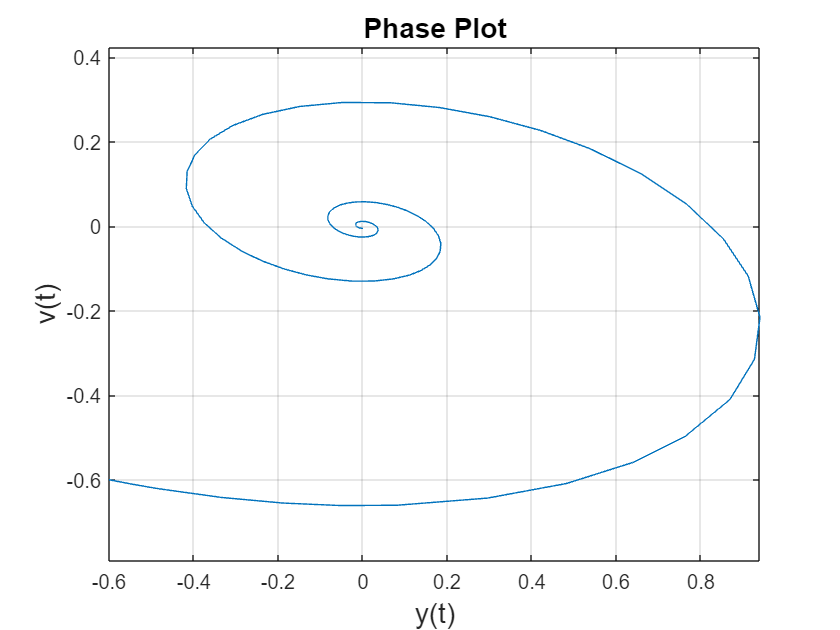

LAB05ex4; close % restore variables

figure; plot(v,y)
title("Phase Plot","FontSize",14)
xlabel("y(t)","FontSize",14)
ylabel("v(t)","FontSize",14)
axis equal; grid on

Since the **mechanical energy** is not conservd in this system, the mass will stop oscillating at some time.

As a result, the graph would get closer and closer to the origin as time gose on.